# **Red lineal para regresión**

## Vimos en la sesión anterior cómo simular una sola célula neuronal (IF). Sin embargo, nuestro sistema nervioso contiene millones de células neuronales individuales que generan algunas redes neuronales. Las redes de neuronas generalmente se optimizan mediante métodos de aprendizaje para obtener la decisión final más cercana a la realidad. Así que en las próximas sesiones veremos cómo simular diferentes tipos de redes neuronales.

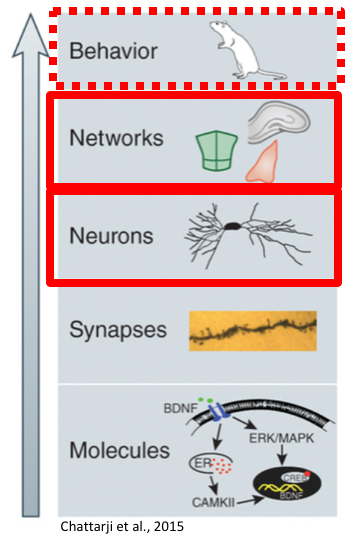

A finales de la década de 1950, los neurólogos Warren McCulloch y Walter Pitts publicaron el primer trabajo sobre redes neuronales, con un artículo fundacional: *Lo que el ojo de la rana le dice al cerebro de la rana*. Luego constituyeron un modelo simplificado de neurona biológica comúnmente llamada neurona formal. Demostraron que las redes neuronales formales simples teóricamente pueden realizar funciones lógicas, aritméticas y simbólicas complejas. La neurona formal está diseñada como un automatismo con una función de transferencia que transforma sus **entradas en salidas** de acuerdo con reglas específicas

Por ejemplo, una neurona **suma sus entradas**, compara la suma resultante con un valor umbral y responde emitiendo una señal si esta suma es mayor o igual a este umbral (modelo ultra simplificado del metabolismo de una neurona biológica). Estas neuronas también están asociadas en **redes** con una topología de conexiones variable: proactiva, recurrente, etc. Finalmente, la eficiencia de la transmisión de señales de una neurona a otra puede variar: hablamos de "peso sináptico", y estos pesos pueden ser modulado por **reglas de aprendizaje** (que imitan la plasticidad sináptica de las redes biológicas).

En este cuaderno, no simularemos una neurona formal porque la suma resultante de entradas no se comparará con un umbral (función de umbral que define la respuesta de la neurona) sino que dependerá de una función lineal. Sin embargo, la topología de la red es bastante similar.

Input layer:

- Data: *inputs* (**X**)

- To improve the computation, in machine learning the Input dataset is usually split into two datasets: *training* and *validation*.

Output layer:

- Weights: **w** (synaptic weights)

- Activation function of a neuron: y = **w' * x **(scalar product between inputs and weights)

- Neuronal response: **linear** **regression **(in that case)

- Error: **E, **mean squared error for these weights (in linear regression)

- Output: **Y**

## **1. Datos sintéticos**

Primero crearemos unos datos sintéticos para estar seguros de que nuestro código funciona correctamente. Para ello usaremos una función lineal del tipo$Y\left(X\right)=\mathrm{a}X+b$. Añadiremos ruido gaussiano ($\mu =0,\sigma =20$, usaremos la función de Matlab rand**n**) a estos datos para que el aprendizaje de la red no sea demasiado fácil. Para crearlos seleccionaremos aleatoriamente un número de muestras (o patrones) de una **distribución uniforme** entre 0 y 10 (usaremos la función de Matlab rand).

clear 
close all

% parámetros "verdaderos"
a = 6;
b = 40;
% Conjunto de entrenamiento, número de muestras
pattern_num = 50; % un numero 

X = 10*rand(1,pattern_num); % input (muestreo aleatorio de una distribución uniforme entre 0 y 10 de una cantidad 'pattern_num' de puntos) 
Y = a*X + b; % nuestra funcion lineal Y(X)
sigmaG = 20; % desviación típica del ruido
G = randn(1,pattern_num)*sigmaG; % ruido gaussiano 
Ynoise = Y + G;       % Ynoise = Y + ruido gaussiano

**1.1** **DATOS** - Haz una gráfica donde se muestre el conjunto de entrenamiento y la relación entre los inputs (X) y los targets (la función lineal con ruido, Ynoise, y sin ruido, Y).

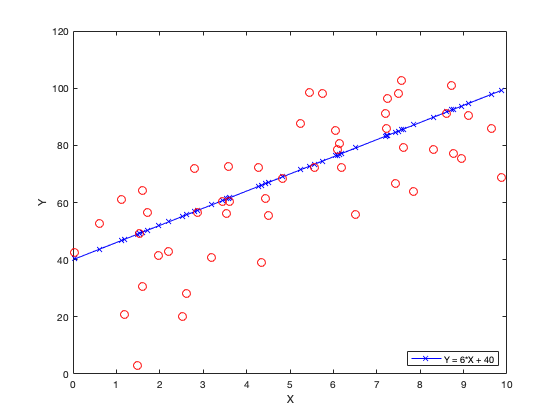

figure(1)
set(gcf, 'name','regresion lineal')
plot(X, Y, 'bx-')
hold on
plot(X,Ynoise, 'ro', 'linestyle', 'none', 'markersize', 8) %plot de los inputs y los puntos de ynoise 
set(gca, 'fontsize', 10)
xlabel('X'), ylabel('Y')
xlim([0 10])
legend({'Y = 6*X + 40'},'Location','SouthEast')

**1.2 RED - **Implementa una red lineal para solucionar esta regresión. Esta red todavía no habrá aprendido los parámetros correctos. Calcula este error inicial y muestra la respuesta inicial de la red a los patrones de aprendizaje (observa el rango del eje de ordenadas en este caso en relación al rango de la Y en la gráfica anterior ).

*Nota sobre el producto escalar*:

El producto escalar de dos vectores $\mathit{\mathbf{u}}=\left\lbrack \begin{array}{c}
u_0 \\
u_1 
\end{array}\right\rbrack$ y $\mathit{\mathbf{v}}=\left\lbrack \begin{array}{c}
v_0 \\
v_1 
\end{array}\right\rbrack$ es igual a $\mathit{\mathbf{u}}\ldotp \mathit{\mathbf{v}}=u_0 v_0 +u_1 v_1$. Podemos escribir el producto escalar como una multiplicación matricial también: 


$${\mathit{\mathbf{u}}\ldotp \mathit{\mathbf{v}}=\mathit{\mathbf{u}}}^{\mathit{\mathbf{T}}} \times \mathit{\mathbf{v}},$$


donde ${\mathit{\mathbf{u}}}^{\mathit{\mathbf{T}}}$ es la transpuesta de $\mathit{\mathbf{u}}$ (operación que cambia filas en columnas). En Matlab la transpuesta de u se escribe " u' ". Aquí*** u*** se refiere a los pesos y ***v*** a las entradas.

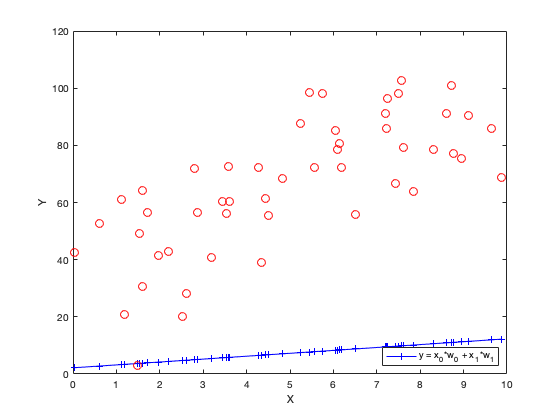

x = [ones(1,pattern_num);X];% añade una fila de unos a los inputs para tener:
                             % x =  1  1  1  ...
                             %      X1 X2 X3 ...
w = randn(2,1); % inicializa vector columna de pesos a valores aleatorios con distribución normal N(0,1)
y = w'*x; % activación de la red (producto escalar entre el input y los pesos)

figure(2)

plot(X, y, 'b+-') % Grafica la activación de la red que resulta de los pesos aleatorios
hold on
plot( X, Ynoise, 'ro', 'linestyle', 'none', 'markersize', 8) % Grafica los datos
xlabel('X')
ylabel('Y')
legend({'y = x_0*w_0 + x_1*w_1'},'Location','SouthEast')


E = calculaError(x,w,Ynoise); % Usaremos el error cuadrático medio divido por 2!!: E = (1/2)*(1/N) * sum ((y - Y) ^ 2). Ver la función llamada 'calculaError'
disp(['El error obtenido usando los pesos iniciales es de: ' num2str(E)])

El error obtenido usando los pesos iniciales es de: 1956.8825


**1.3** **Aprendizaje **

Para el aprendizaje hay que completar la función `descensoGradiente.m``. `Entrena la red para que aprenda la función que relaciona los inputs y los targets. Tendrás que encontrar el valor de alpha por prueba y error hasta que la red consiga un buen aprendizaje. Recuerda que el aprendizaje debería llegar a un minimo de la función de error. Esto quiere decir que el error disminuirá con las iteraciones hasta estabilizarse en un valor (esperablemente, pero no necesariamente, cercano al cero). Si el error está bajando pero no es estable al terminar el aprendizaje quiere decir que necesitamos mas iteraciones (o un alpha mas grande). Si el error no baja seguramente necesitemos un alpha mas pequeño.

Comprueba que: $\vec{\bigtriangledown} \textrm{Err}=\left\lbrack \begin{array}{c}
\frac{\partial \textrm{Err}}{\partial w_0 }\\
\frac{\partial \textrm{Err}}{\partial w_1 }
\end{array}\right\rbrack =\frac{1}{N}\left\lbrack \begin{array}{c}
\sum_{i=1}^N e_i \\
\sum_{i=1}^N X_i e_i 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
\textrm{mean}\left(e\right)\\
\textrm{mean}\left(X\ldotp e\right)
\end{array}\right\rbrack$, donde $e_i =\left(y_i -Y_i \right)$. Esto lo podemos escribir también en formato matlab:


$$\vec{\bigtriangledown} \textrm{Err}=\textrm{mean}\left(\left\lbrack \begin{array}{ccc}
e_1  & e_2  & \ldotp \ldotp \ldotp \\
e_1 X_1  & e_2 X_2  & \ldotp \ldotp \ldotp 
\end{array}\right\rbrack ,2\right)$$


En esta función, tendrás que:

- inicializar aleatoriamente los pesos.

- crear la ecuación de gradiente de descenso ($\nabla E$) 

- actualizar los pesos ($w_{i+1}$). 

- esto se repetirá hasta el criterio de parada ($\|\nabla E\|$) para cada entrada

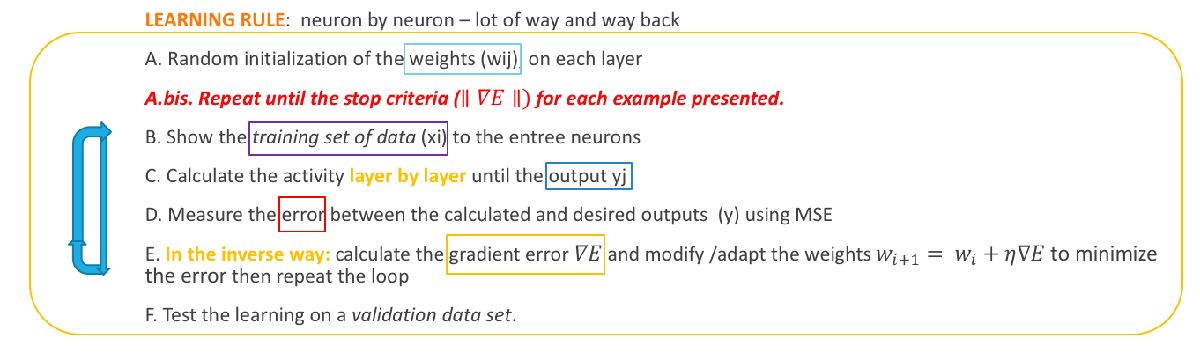

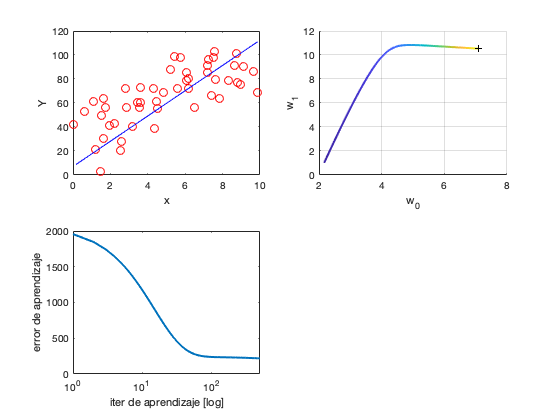

num_iter = 500; % numero total de iteraciones, conviene parar cuando el error ya no baja más (~mismo valor en varias iteraciones)
alpha = 1e-3 ; % paso de aprendizaje, learning rate. Si es muy alto puede imposibilitar la convergencia al mínimo, si es muy bajo el proceso será lento.

[w_opt, E_hist] = descensoGradiente(x,w,Ynoise,alpha,num_iter,true); % completar funcion

**1.4 TRAIN - VAL** El error de aprendizaje solo nos muestra cuanto se equivoca la red con los datos que hemos usado para el entrenamiento pero normalmente queremos que la red sea capaz de predecir los valores correctos (dentro de un margen de error) también para datos nuevos (generalización). Usaremos la función `trainvalset_LR.m` para separar los datos en un conjunto de entrenamiento (que usaremos para el aprendizaje) y un conjunto de validación (datos nuevos que la red no ha visto en entrenamiento). Modificaremos la función `descensoGradiente.m` para que calcule también el error sobre el conjunto de validación. Doncs, vamos a crear una nueva función llamada "descensoGradiente_val".

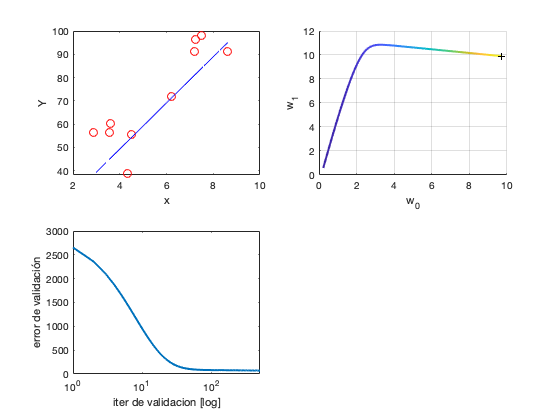

% separa los datos en training y validacion
frac_train = .8;  % fraccion de datos para el training del 80%
[Xtrain, Ytrain, Xval, Yval] = trainvalset_LR(X,Ynoise, frac_train);

% agregamos la fila de 1's
xtrain = [ones(1,length(Xtrain)); Xtrain]; 
xval = [ones(1,length(Xval)); Xval];

w = randn(2,1); % inicializa vector de pesos a valores aleatorios con distribución normal N(0,1)
num_iter = 500; % número total de iteraciones
alpha = 1e-3; % paso de aprendizaje

% modificar la función descensoGradiente para que calcule tambien el error de validacion y lo devuelva como output
% (crear nueva función basándose en la completada antes (copy/paste))
[w, E_hist, E_val_hist] = descensoGradiente_val(xtrain,w,Ytrain,xval,Yval,alpha,num_iter,true);

**1.5** Para estudiar el efecto del número de patrones en el aprendizaje crea nuevos datos de manera parecida al primer apartado pero usando distintos valores de `pattern_num `y una `sigmaG de` 30. Con estos valores hay mucho ruido y las muestras pueden ser muy diferentes entre ellas cada vez que ejecutemos el código. Repite el entrenamiento y la validación con diferente número de patrones y comenta el resultado.

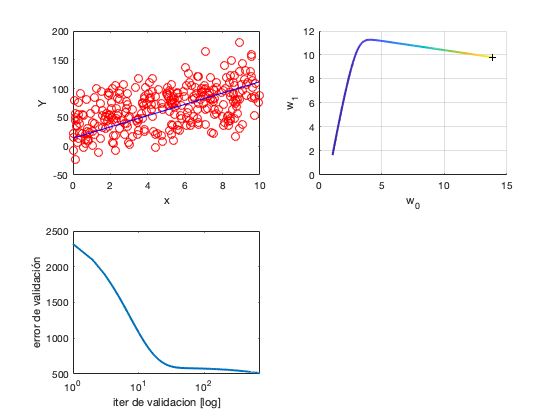

clear 

% Conjunto de entrenamiento, número de muestras
pattern_num = 600; 
a = 6;
b = 40;

X = 10*rand(1,pattern_num); % input (muestreo aleatorio de una distribución uniforme entre 0 y 10 de una cantidad 'pattern_num' de puntos) 
Y = a*X + b; % nuestra funcion lineal Y(X)
sigmaG = 30; % desviación típica del ruido
G = randn(1,pattern_num)*sigmaG; % ruido gaussiano 
Ynoise = Y + G;       % Ynoise = Y + ruido gaussiano

% separa los datos en training y validacion
frac_train = .5;  % fraccion de datos para el training 
[Xtrain, Ytrain, Xval, Yval] = trainvalset_LR(X,Ynoise, frac_train);

% agregamos la fila de 1's
xtrain = [ones(1,length(Xtrain)); Xtrain]; 
xval = [ones(1,length(Xval)); Xval];

w = randn(2,1); % inicializa vector de pesos a valores aleatorios con distribución normal N(0,1)
num_iter = 700; % número total de iteraciones
alpha = 1e-3; % paso de aprendizaje

[w, E_hist, E_val_hist] = descensoGradiente_val(xtrain,w,Ytrain,xval,Yval,alpha,num_iter,true);

**Comentario: Con este tipo de datos aleatorios es muy complicado aprender, y el error no termina de llegar a 0. Pero a medida que subimos el numero de muestras, cada vez se va haciendo un poco más precisa.**

**1.6** Prueba con un conjunto de datos no lineal. ¿La red es capaz de aprender? Comenta el resultado.

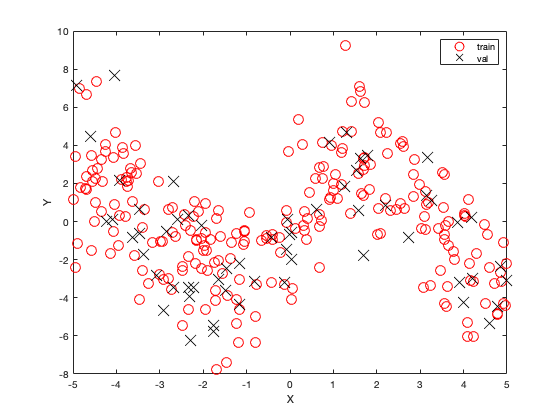

clear 

% conjunto de entrenamiento
pattern_num = 300;
X = rand(1,pattern_num)*10-5; % input (mostreo aleatorio de una distribución uniforme entre -5 y 5)
sigmaG = 1; % desviación estandar del ruido
G = randn(1,pattern_num)*sigmaG; % ruido gaussiano
Y = 3*sin(X) + G; % función
Ynoise = Y + G; % Ynoise = Y + ruido gaussiano

frac_train = .8;
[Xtrain, Ytrain, Xval, Yval] = trainvalset_LR(X, Ynoise, frac_train);

% agregamos la fila de 1's
xtrain = [ones(1,length(Xtrain)); Xtrain]; 
xval = [ones(1,length(Xval)); Xval];

% % visualizamos el conjunto de entrenamiento y validacion
figure
set(gcf,'name','regresion lineal')
plot(Xtrain, Ytrain, 'ro', 'linestyle', 'none', 'markersize', 10)
hold on
plot(Xval, Yval, 'kx', 'linestyle', 'none', 'markersize', 14)
set(gca, 'fontsize', 10)
legend({'train','val'})
xlabel('X')
ylabel('Y')

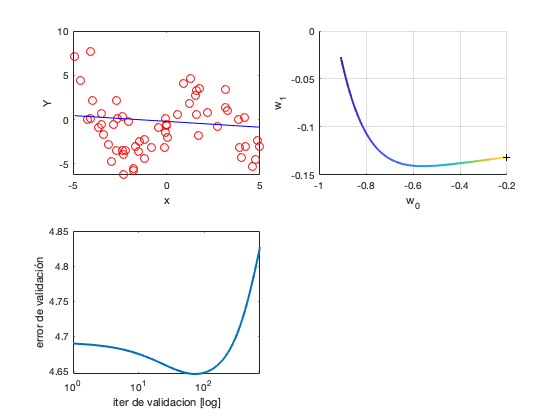



w = randn(2,1); % inicializa vector de pesos a valores aleatorios con distribución normal N(0,1) 

num_iter = 700; % número total de iteraciones
alpha = 1e-3; % paso de aprendizaje

[w_opt, E_hist, E_val_hist] = descensoGradiente_val(xtrain,w,Ytrain,xval,Yval,alpha,num_iter,true); % completar función

**Comentario: Una red neuronal que ha aprendido usando un conjunto de datos lineales no debería poder predecir con mucha exactitud el resultado de datos no lineales.**

## 2. Datos reales

Vamos a predecir los beneficios de una tienda basándonos en la poblacion de la ciudad. Estos datos estan en el fichero `linear_data.txt:` en la primera columna están los valores del tamaño de la ciudad por cada 10000 habitantes y en la segunda columna están los valores de los beneficios de algunas tiendas en 10000 $ (beneficios negativos son perdidas).

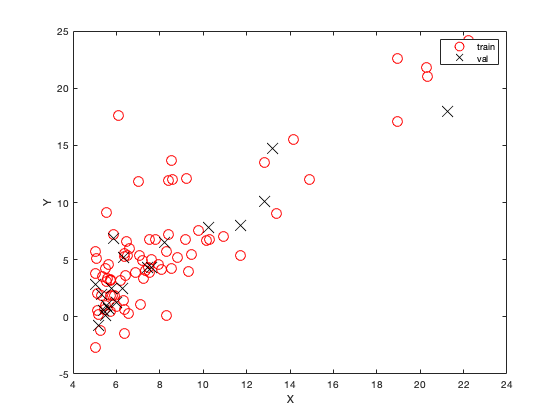

clear

data = load('linear_data.txt');
[Xtrain, Ytrain, Xval, Yval] = trainvalset_LR(data(:,1)', data(:,2)', .8);

% agregamos la fila de 1's
xtrain = [ones(1,length(Xtrain)); Xtrain]; 
xval = [ones(1,length(Xval)); Xval];

% % visualizamos el conjunto de entrenamiento y validacion
figure
set(gcf,'name','regresion lineal')
plot(Xtrain, Ytrain, 'ro', 'linestyle', 'none', 'markersize', 10)
hold on
plot(Xval, Yval, 'kx', 'linestyle', 'none', 'markersize', 14)
set(gca, 'fontsize', 10)
legend({'train','val'})
xlabel('X')
ylabel('Y')

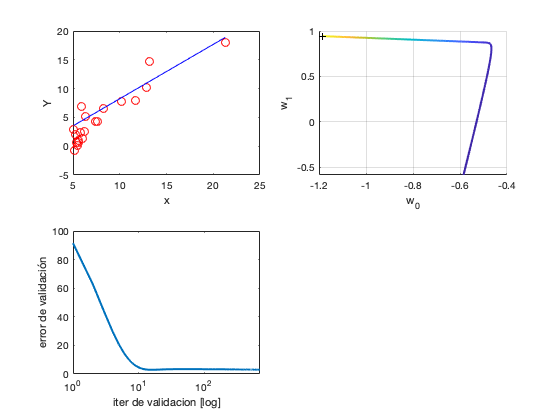



w = randn(2,1); % inicializa vector de pesos a valores aleatorios con distribución normal N(0,1) 

num_iter = 700; % número total de iteraciones
alpha = 1e-3; % paso de aprendizaje

[w_opt, E_hist, E_val_hist] = descensoGradiente_val(xtrain,w,Ytrain,xval,Yval,alpha,num_iter,true); % completar función